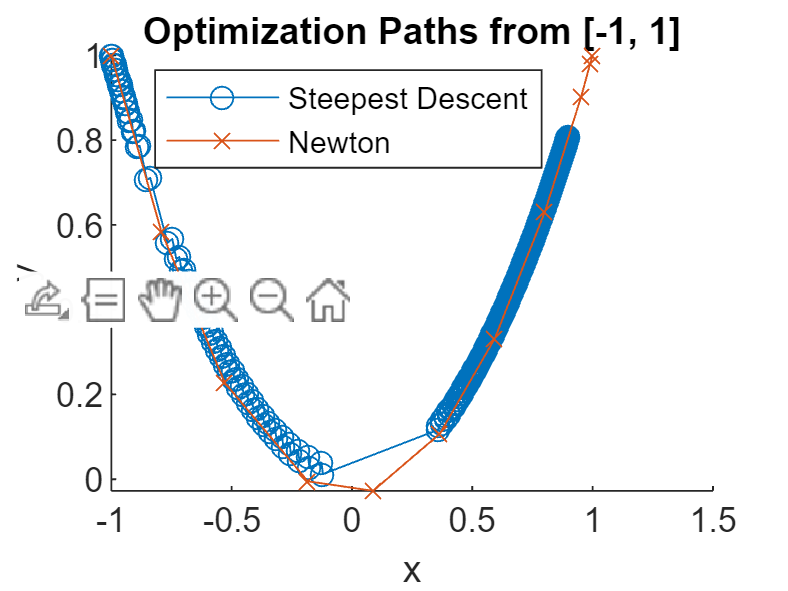

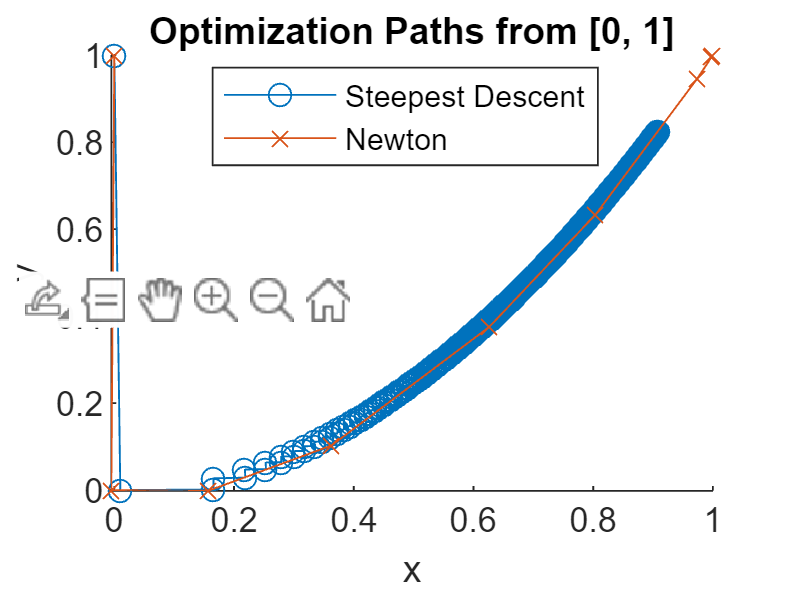

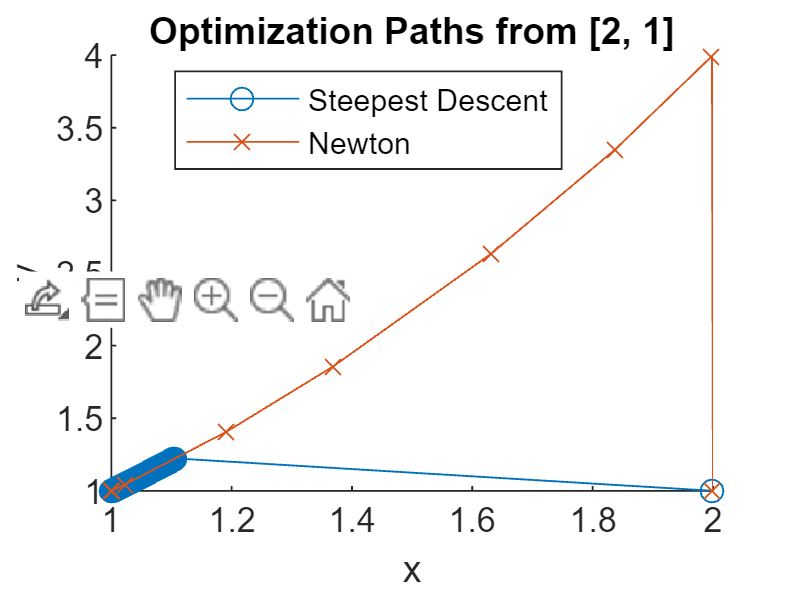

% Define starting points
starting_points = [-1 1; 0 1; 2 1];

% Define the Rosenbrock function and its derivatives
f = @(x) 100*(x(2) - x(1)^2)^2 + (1 - x(1))^2;
grad_f = @(x) [-400*x(1)*(x(2) - x(1)^2) - 2*(1 - x(1));
               200*(x(2) - x(1)^2)];
hess_f = @(x) [-400*(x(2) - 3*x(1)^2) + 2, -400*x(1);
               -400*x(1), 200];

% Optimization parameters
max_iter = 1000;
tol = 1e-6;

% Loop over starting points
for i = 1:size(starting_points, 1)
    x0 = starting_points(i, :)';

    % Steepest Descent
    [x_sd, path_sd] = steepest_descent(f, grad_f, x0, max_iter, tol);

    % Newton's Method
    [x_newton, path_newton] = newton_method(f, grad_f, hess_f, x0, max_iter, tol);

    % Plotting
    figure;
    hold on;
    plot(path_sd(1, :), path_sd(2, :), '-o', 'DisplayName', 'Steepest Descent');
    plot(path_newton(1, :), path_newton(2, :), '-x', 'DisplayName', 'Newton');
    legend;
    title(sprintf('Optimization Paths from [%d, %d]', x0(1), x0(2)));
    xlabel('x');
    ylabel('y');
    hold off;
end

function [x, path] = steepest_descent(f, grad_f, x0, max_iter, tol)
    x = x0;
    path = x;
    for i = 1:max_iter
        grad = grad_f(x);
        if norm(grad) < tol
            break;
        end
        alpha = fminsearch(@(alpha) f(x - alpha*grad), 0);
        x = x - alpha * grad;
        path = [path, x];
    end
end

function [x, path] = newton_method(f, grad_f, hess_f, x0, max_iter, tol)
    x = x0;
    path = x;
    for i = 1:max_iter
        grad = grad_f(x);
        if norm(grad) < tol
            break;
        end
        H = hess_f(x);
        p = -H\grad; % Equivalent to solving Hp = -grad
        alpha = fminsearch(@(alpha) f(x + alpha*p), 0);
        x = x + alpha * p;
        path = [path, x];
    end
end
